clear all; close all;
ones([1, 2]);

time = 0 : 0.01 : 10;
x0 = [0;0;0];
x = zeros(length(time), 3);

Earth;
F = [0; 0; 0];
a = F./(m*w0*R0)

a =      0
     0
     0



r = sqrt((x(1) + 1)^2 + x(2)^2 + x(3)^2);
dx(1) = x(4);
dx(2) = x(5);
dx(3) = x(6);
dx(4) = 2*x(5) + (1 + x(1))*(1 - r^(-3)) + a(1);
dx(5) = -2*x(4) + x(2)*(1 - r^(-3)) + a(2);
dx(6) = -x(3)*r^(-3) + a(3);


u = [0 0 0];
MDNS = 100;
size(u)

ans =      1     3



%Polozenie poczatkowe wzgledem Ziemi
Rz = 6.37314*1e6;
x0z = [7e5; 0; 0] + Rz;

v0z = [0 ;7.9196 *1e3; 0];
x0z = [x0z; v0z];

[x0sk, v0sk] = r2x_transform(x0z(1:3), x0z(4:6), 0)

x0sk =    -0.8326
    0.1509
    0.1509


v0sk =     0.1509
    2.4106
         0


tau = [10]';

Rz = 6.37314*1e6;
R0 = Rz + 7e5;%4.2242e7;
x0 = [R0;0;0];

%rhat = norm(x0);
%r = x0/rhat;

G = 6.67e-11;
M = 5.98e24;
    
v0 = sqrt(G*M/R0) * [0; 0; 1];



[x0sk, v0sk] = r2x_transform(x0, v0, 0);
x0 = [x0sk; v0sk]

x0 =    -0.8326
         0
         0
         0
   -0.1674
    2.4445


% x0 = [0;0;0;0;0;0]

[t,x,~,~] = get_tx(tau,u,x0,MDNS);
t1=t*86400/(2*pi);

xorb=zeros(length(t),6);
for k=1:length(t)
    [xEarth, vEarth] = x2r_transform(x(k, 1:3)', 0, t1(k));
    xorb(k,:)= [xEarth; vEarth];
end 


figure;
% plot3(xorb(:,1), xorb(:,2), xorb(:,3))
printOrbit(xorb(:,1), xorb(:,2), xorb(:,3));

grid on;





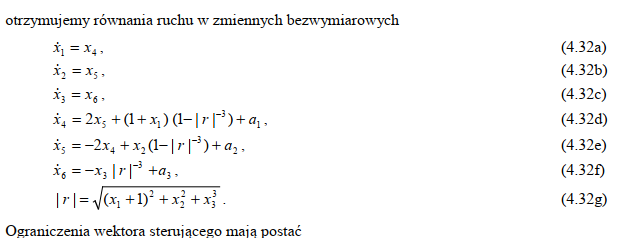

clear;close all;
nu=5;
tf=5;
umax=1;
umin=-1;
tau=(tf/nu)*[1:nu]';
uopt=zeros(nu,3);
Rz = 6.37314*1e6;
%R0 = Rz + 7e5;
R0 = 4.2242e7;
R0 = R0;
x0 = [R0+1e6;1e6;0];
G = 6.67e-11;
M = 5.98e24;
v0 = sqrt(G*M/R0) * [0; 0; 1];
[x0sk, v0sk] = r2x_transform(x0, v0, 0);
v0sk = [0;0;0]

v0sk =      0
     0
     0



% Definicje początkowe
x0 = [x0sk; v0sk; 0];            % Stan początkowy (pozycja + prędkość)
xf = [0; 0; 0; 0; 0; 0];      % Stan końcowy (zero)
W = eye(length(xf));               % Waga w funkcji kosztu (tu zerowa)
MDNS = 5*1e2;                   % Ilość kroków dyskretyzacji

% Definicja funkcji kosztu
qh = @(uopt) cost_fun_s(uopt, tau, x0, xf, W, MDNS);

% Parametry optymalizacji
nu = length(uopt);            % Liczba zmiennych sterowania
LB = -ones(nu,1);             % Dolne ograniczenia na uopt
UB = ones(nu,1);              % Górne ograniczenia na uopt

% Opcje dla fmincon
options = optimoptions('fmincon');
options.SpecifyObjectiveGradient = false;
options.Display = 'iter';
options.Algorithm = 'interior-point';

% Rozwiązanie problemu optymalizacji
uopt = fmincon(qh, uopt, [], [], [], [], LB, UB, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      16    1.010495e+00    0.000e+00    1.989e-01
    1      32    8.789365e-01    0.000e+00    1.364e-01    4.082e-01
    2      48    7.967395e-01    0.000e+00    1.000e-01    6.398e-01
    3      64    7.935557e-01    0.000e+00    3.660e-02    7.383e-02
    4      80    7.784132e-01    0.000e+00    4.469e-02    4.572e-01
    5      96    7.644257e-01    0.000e+00    3.923e-02    5.541e-01
    6     112    7.526518e-01    0.000e+00    1.893e-02    6.357e-01
    7     128    7.504177e-01    0.000e+00    5.322e-03    1.475e-01
    8     144    7.502014e-01    0.000e+00    1.917e-03    4.785e-02
    9     160    7.501844e-01    0.000e+00    1.229e-03    1.583e-02
   10     176    7.501753e-01    0.000e+00    1.370e-03    6.495e-03
   11     192    7.501587e-01    0.000e+00    2.000e-03    1.128e-02
   12     208    7.501296e-01    0.000e+00    2

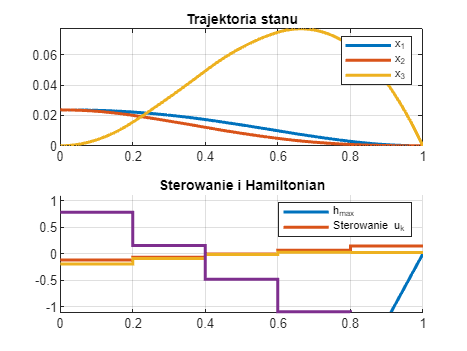


% Symulacja trajektorii
[t, x, uk, nseg] = get_tx_s(tau, uopt, x0, MDNS);

% Liczenie współczynnika adjoint (co-state)
pf = [-W * (x(end,1:end-1)' - xf); 0];
p = rk4p_s(pf, t, x, uk);

% Liczenie wartości hamiltonianu
hmax = get_hmax(t, p, x, uk);

% Rysowanie wyników
figure;

subplot(2,1,1);
h = plot(t, [x(:,1), x(:,2), x(:,3)]);
set(h, 'LineWidth', 2);
title('Trajektoria stanu');
legend('x_1', 'x_2', 'x_3');
grid on;

subplot(2,1,2);
hold on;
h1 = plot(t, hmax);
h2 = stairs(t, uk);
set([h1; h2], 'LineWidth', 2);
axis([0 t(end) -1.1 1.1]);
title('Sterowanie i Hamiltonian');
legend('h_{max}', 'Sterowanie u_k');
grid on;
hold off;

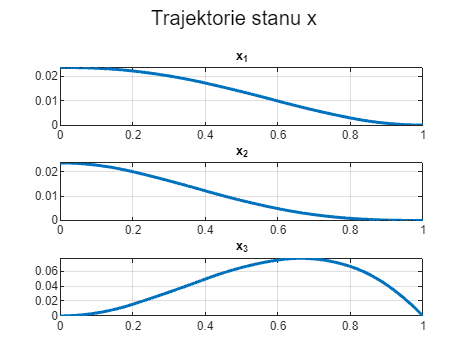

% === Wykres 1: Trajektorie stanu ===
figure;
for i = 1:3
    subplot(3,1,i);
    plot(t, x(:,i), 'LineWidth', 2);
    title(['x_', num2str(i)]);
    grid on;
end

sgtitle('Trajektorie stanu x');

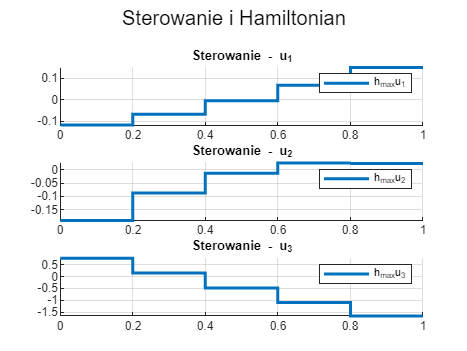


% === Wykres 2: Sterowanie i Hamiltonian ===
figure;
for i = 1:3
    subplot(3,1,i);
    hold on;
    %plot(t, hmax, 'LineWidth', 2);
    stairs(t, uk(:,i), 'LineWidth', 2);
    title(['Sterowanie - u_', num2str(i)]);
    legend(['h_{max}', 'u_', num2str(i)]);
    axis tight
    grid on;
    hold off;
end

sgtitle('Sterowanie i Hamiltonian');

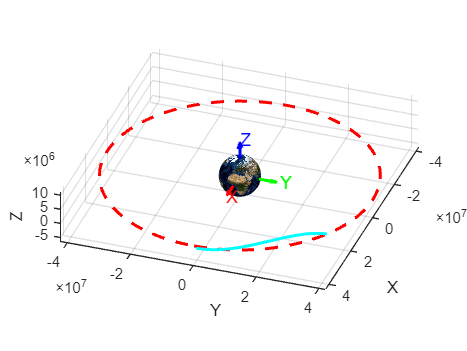

t1=t*86400/(2*pi);
xorb=zeros(length(t1),6);
for k=1:length(t1)
    [xEarth, vEarth] = x2r_transform(x(k, 1:3)', 0, t1(k));
    xorb(k,:)= [xEarth; vEarth];
end 

figure;
% plot3(xorb(:,1), xorb(:,2), xorb(:,3))
printOrbit(xorb(:,1), xorb(:,2), xorb(:,3));

grid on;

tau=[.2 .3 .4 .5 .6 .7]';
u=ones(length(tau), 3)*[1 0 0; 0 -1 0 ;0 0 1];
x0=[0;0;0;0;0;0;0];
xf=[pi;0;0;0;0;0];
W=1000*eye(6);
MDNS=1e3;
ep=1e-9;gnum=zeros(6,1);
[q,g]=cost_fun_s(u,tau,x0,xf,W,MDNS);
for k=1:length(tau)
    ei=zeros(6,1);
    ei(k)=1;
    up=u(k,:)+ei*ep;
    um=u(k,:)-ei*ep;
    fp=cost_fun_s(up,tau,x0,xf,W,MDNS);
    fm=cost_fun_s(um,tau,x0,xf,W,MDNS);
    gnum(k)=(fp-fm)/(2*ep);
end
%porownanie g - r. sprz., gnum - rozn.
[g';gnum']

ans =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
 -331.3262 -125.6694 -100.1026  -75.9273  -53.6947  -34.1633
